# T5-02. Getting the autocovariance function from an AR model through MA representation

## Introduction

In this tutorial you will learn how to estimate the autocovariance function of a univariate random process defined by an AR model through Moving Average (MA) representation. 

The advantage of this approach is the reduced memory requirements, as compared to the computation of the exact autocovariance function. This is specially relevant for the multivariate case. 

The underlying idea is that an AR process can be represented through a MA($\infty$) process. Truncation to order $q$ of the MA model order leads to an imperfect representation of the AR process, thus, the autocovariance function of the MA model approximates that of the AR model. The accuraty of the approximation decays for lags close to $q$. For this reason, large $q$ values should be considered for accurate estimations of the AR autocovariance function. For details, see **[1]**.

To learn about computing the exact autocovariance function of an AR model, see tutorial '*getting_gamma_from_AR*'.

The dataset employed in this tutorial is '*datasets/dataset_01_AR*', which includes a restricted AR model employed in Section 3.1 of** [1]**. 

**[1]** Gallego-Castillo, C. et al., A tutorial on reproducing a predefined autocovariance function through AR models: Application to stationary homogeneous isotropic turbulence, Stochastic Environmental Research and Risk Assessment. DOI: 10.1007/s00477-021-02156-0 

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

M = 25;     % máximum lag considered for gamma 

q = 10;     % MA order


%%% Plot parameters
font_size       = 18;
figure_position = [0 0 1000 400];
CC = colororder;
color_AR        = CC(1,:);
color_MA        = CC(3,:);

Load the dataset. It consists of a restricted AR model. 

load dataset_01_AR AR

fprintf('j_vector is [%d, %d, %d] \n', AR.restricted_parameters.j_vector)

j_vector is [1, 2, 5] 


fprintf('a_vector is [%.1f, %.1f, %.1f] \n', AR.restricted_parameters.a_vector)

a_vector is [1.2, -0.5, 0.1] 


fprintf('b is %.1f \n',AR.restricted_parameters.b)

b is 0.5 


Check the fields required by function `get_gamma_AR` and `get_gamma_AR_through_MA`. For details related to the fields of these objects, see functions `initialise_`AR.

Initialise a `gamma_fun` object with the fields required by function `get_gamma_data`.

[gamma_fun0] = initialise_gamma('M', M);

Compute the exact autocovariance function of the AR model. 

[gamma_AR] = get_gamma_AR(AR, gamma_fun0);

Compute the approximated autocovariance function of the AR model through MA representation.

[gamma_MA] = get_gamma_AR_through_MA(AR, gamma_fun0, q);

Compare the obtained autocovariance functions.

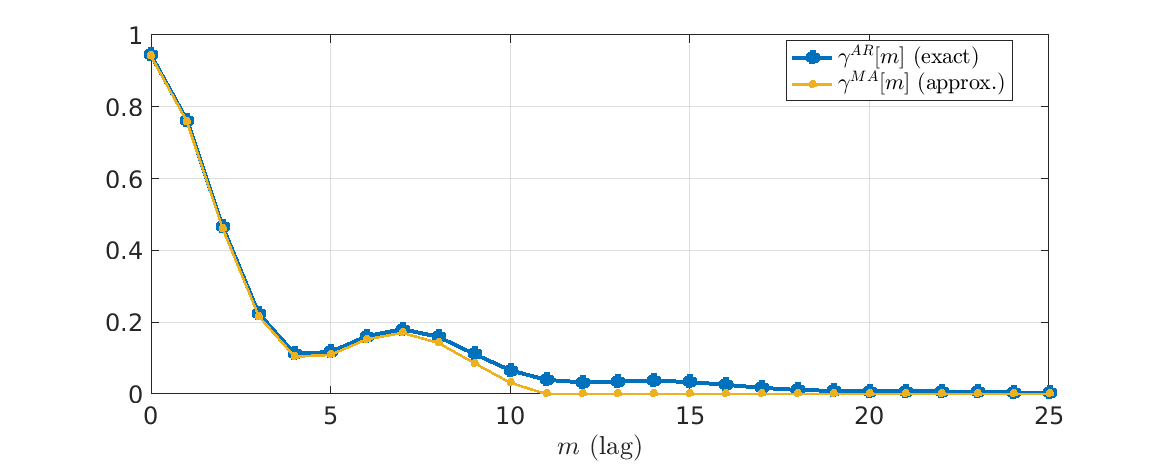

figure

x = gamma_AR.xlag_values;
y = gamma_AR.y_values;
plot(x,y,'O-','LineWidth',3,'MarkerSize',8,...
     'color',color_AR,'MarkerFaceColor',color_AR)

hold on

x = gamma_MA.xlag_values;
y = gamma_MA.y_values;
plot(x,y,'O-','LineWidth',2,'MarkerSize',5,...
     'color',color_MA,'MarkerFaceColor',color_MA)

grid on
xlim([0 M])
legend({'$\gamma^{AR}[m]$ (exact)', ...
        '$\gamma^{MA}[m]$ (approx.)'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$m$ (lag)','Interpreter','latex')

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

## Remarks

- The accuracy of the estimated autocovariance function of the AR model through MA representation, $\gamma^{MA}[m]$ depends strongly on the MA model order, $q$. Change this parameter to check this effect.